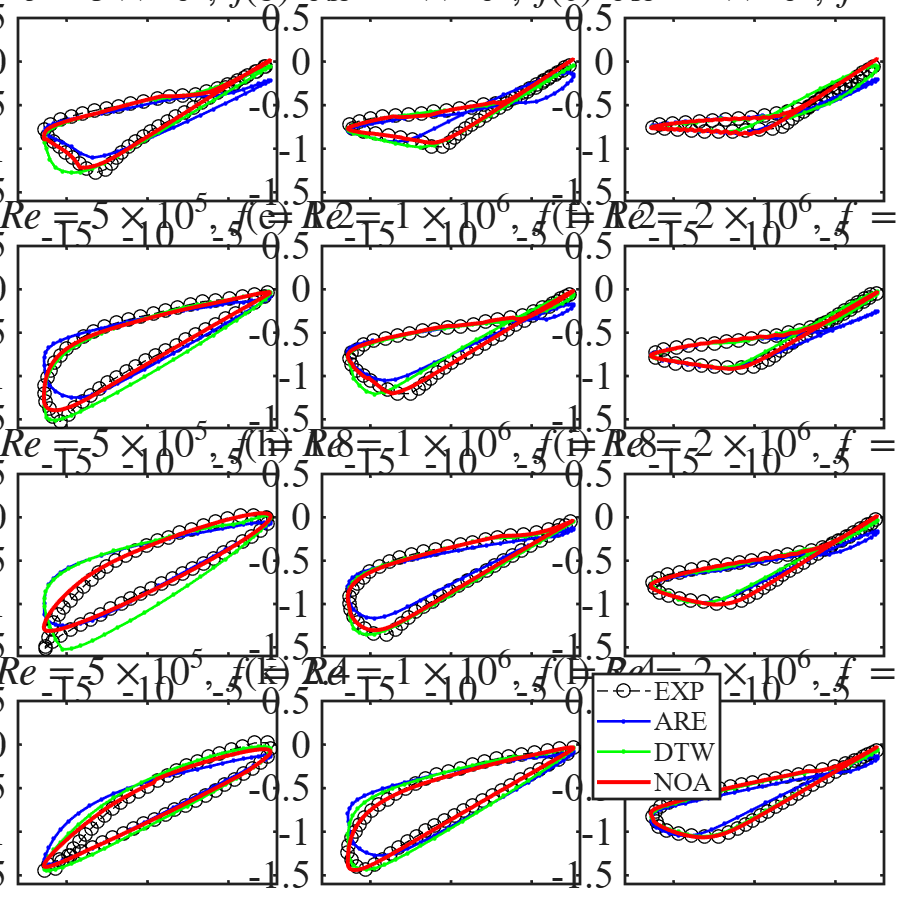

%% Main program:Iterate through subfolders and load selected.matfile
clear; clc; close all; warning off; addpath(genpath(pwd));

% -------------------------- 1. Set root folder path --------------------------
mainFolder = 'compare_DTW_ARE_MSE_GZ_v2/';
folder     = {
    '-9.4±7_re5e5_0.6',...
    '-9.4±7_re1e6_0.6',...
    '-9.4±7_re2e6_0.6',...
    '-9.4±7_re5e5_1.2',...
    '-9.4±7_re1e6_1.2',...
    '-9.4±7_re2e6_1.2',...
    '-9.4±7_re5e5_1.8',...
    '-9.4±7_re1e6_1.8',...
    '-9.4±7_re2e6_1.8',...
    '-9.4±7_re5e5_2.4',...    
    '-9.4±7_re1e6_2.4',...            
    '-9.4±7_re2e6_2.4',...
    % '9.6±7_re5e5_0.6',...
    % '9.6±7_re1e6_0.6',...
    % '9.6±7_re2e6_0.6',...
    % '9.6±7_re5e5_1.2',...
    % '9.6±7_re1e6_1.2',...
    % '9.6±7_re2e6_1.2',...
    % '9.6±7_re5e5_1.8',...
    % '9.6±7_re1e6_1.8',...
    % '9.6±7_re2e6_1.8',...
    % '9.6±7_re5e5_2.4',...
    % '9.6±7_re1e6_2.4',...
    % '9.6±7_re2e6_2.4',...
    };

% -------------------------- 3. Iterate through subfolders and load.matfile --------------------------
% Define files to search for.matfile-name list
targetMatFiles = {
    'data_collection_ARE.mat'
    'data_collection_DTW.mat'
    'data_collection_GZ.mat'
};
pattern = '^([^±]+)±.*?_re([^_]+)_(.+)$';
fontsize = 30;
line1 = 2;
line2 = 3;
mksize = 10;
lgdwidth = 40;
fig1 = figure('Color','w','Position',[100 100 2400 2400]);



Error_S = zeros(length(folder),4);
Error_M = zeros(length(folder),4);
Error_m = zeros(length(folder),4);
Error_cob = zeros(length(folder),4);
Error_ARE = zeros(length(folder),3);
Error_DTW = zeros(length(folder),3);
Error_GZ = zeros(length(folder),3);


% colors = [
%     248/255 172/255 140/255;     % Red(Category1)
%     154/255 201/255 219/255;     % Blue(Category2)
%     255/255 136/255 132/255;     % Green(Category3)
%     140/255 172/255 248/255;   % Orange(Category4)
% ];

% colors = [
%     161/255 169/255 208/255;     % Red(Category1)
%     240/255 152/255 140/255;     % Blue(Category2)
%     184/255 131/255 212/255;     % Green(Category3)
%     158/255 158/255 158/255;   % Orange(Category4)
% ];

% colors = [
%     142/255 207/255 201/255;     % Red(Category1)
%     255/255 190/255 122/255;     % Blue(Category2)
%     250/255 127/255 111/255;     % Green(Category3)
%     130/255 176/255 210/255;   % Orange(Category4)
% ];

colors = [
    'k';     % Red(Category1)
    'b';     % Blue(Category2)
    'g';     % Green(Category3)
    'r';   % Orange(Category4)
    ];

for i = 1:length(folder)
 % i = 1;
    subFolderName = folder(i);
    subFolderPath = fullfile(mainFolder, subFolderName);    
    validVarName = genvarname(subFolderName);
    currentFolderData = struct();
    
    %===================================Load data===================================
    for j = 1:length(targetMatFiles)
        matFilePath = fullfile(subFolderPath, targetMatFiles{j});

        if j == 1
            load(char(matFilePath))

            S_ARE = trapz(ARE_data(:,1) ,ARE_data(:,2));
            [max_ARE,i_ARE] = max(ARE_data(:,2));
            [min_ARE,j_are] = min(ARE_data(:,2));
            MAX_ARE = [max_ARE,ARE_data(i_ARE,1)];
            MIN_ARE = [min_ARE,ARE_data(j_are,1)];
        elseif j == 2
            load(char(matFilePath));

            S_DTW = trapz(DTW_data(:,1) ,DTW_data(:,2));
            [max_DTW,i_DTW] = max(DTW_data(:,2));
            [min_DTW,j_dtw] = min(DTW_data(:,2));
            MAX_DTW = [max_DTW,DTW_data(i_DTW,1)];
            MIN_DTW = [min_DTW,DTW_data(j_dtw,1)];
        elseif j == 3
            load(char(matFilePath));

            S_GZ = trapz(GZ_data(:,1) ,GZ_data(:,2));
            [max_GZ,i_GZ] = max(GZ_data(:,2));
            [min_GZ,j_gz] = min(GZ_data(:,2));
            MAX_GZ = [max_GZ,GZ_data(i_GZ,1)];
            MIN_GZ = [min_GZ,GZ_data(j_gz,1)];


            S_init= trapz(init_data(:,1) ,init_data(:,2));
            [max_init,i_init] = max(init_data(:,2));
            [min_init,j_init] = min(init_data(:,2));
            MAX_init = [max_init,init_data(i_init,1)];
            MIN_init = [min_init,init_data(j_init,1)];


            S_exp = trapz(exp_data(:,1) ,exp_data(:,2));

            [exp_up,exp_dw] = area_cover(ARE_data,DTW_data,GZ_data,init_data,exp_data);
        
            EXP_data = [exp_up
                        exp_dw];

            [max_EXP,i_EXP] = max(EXP_data(:,2));
            [min_EXP,j_exp] = min(EXP_data(:,2));
            MAX_EXP = [max_EXP,EXP_data(i_EXP,1)];
            MIN_EXP = [min_EXP,EXP_data(j_exp,1)];
        end
        
    end
    %===================================Compute error===================================
    Error_S(i,:) = new_areacover(ARE_data,DTW_data,GZ_data,init_data,exp_data);

    Error_M(i,:) = process_mat_data(MAX_ARE,MAX_DTW,MAX_GZ,MAX_init,MAX_EXP);

    Error_m(i,:) = process_mat_data(MIN_ARE,MIN_DTW,MIN_GZ,MIN_init,MIN_EXP);

    Error_cob(i,:) = (1-Error_S(i,:))*0.7 + Error_M(i,:)*0.15 + Error_m(i,:)*0.15;



    Error_ARE(i,:) = dataprocess_ARE(ARE_data,DTW_data,GZ_data,init_data,EXP_data);

    Error_DTW(i,:) = dataprocess_DTW(ARE_data,DTW_data,GZ_data,init_data,exp_data);
    
    Error_GZ(i,:) = dataprocess_GZ(ARE_data,DTW_data,GZ_data,init_data,EXP_data);



    %===================================Plot figures===================================
    num_pts = 500;

    exp_data = resampleCurveEqualSpacing(exp_data, num_pts);

    ARE_data = [ARE_data(1:end,:)
                ARE_data(1,:)];

    DTW_data = [DTW_data(1:end,:)
                DTW_data(1,:)];

    GZ_data = [GZ_data(1:end,:)
                GZ_data(1,:)];

    init_data = [init_data(1:end,:)
                 init_data(1,:)];

    exp_data = [exp_data(1:end,:)
                exp_data(1,:)];

    match = regexp(folder{i}, pattern, 'tokens');
    meanangle = str2double(match{1}{1});
    Re        = str2double(match{1}{2});
    k         = str2double(match{1}{3});
    coeff = floor(log10(abs(Re)));
    base = Re / 10^coeff;

    padding = 0.02;       
    h_spacing = 0.05;      
    v_spacing = 0.05;     
    n_cols = 3;            
    n_rows = 4;            
    
    subplot_width = (1 - 2*padding - (n_cols-1)*h_spacing) / n_cols;
    subplot_height = (1 - 2*padding - (n_rows-1)*v_spacing) / n_rows; 
    
    c = mod(i,3);
    r = fix(i/3);
    if c == 0
        c=3;
    end
    if i == 3 || i == 6 || i == 9 || i ==12
        r = r-1;
    end

    left = padding + (c-1)*(subplot_width + h_spacing);
    bottom = padding + (3-r)*(subplot_height + v_spacing);
    pos = [left, bottom, subplot_width, subplot_height];


    figure(fig1);
    %===================================Hysteresis-loop plot===================================
    subplot('Position',pos)
    plot(exp_data(1:10:end,1) ,exp_data(1:10:end,2) ,'o--','LineWidth',1,'MarkerSize',mksize,'Color',colors(1))
    hold on
    % scatter(exp_data(1:20:end,1) ,exp_data(1:20:end,2) ,mksize,'o','MarkerEdgeColor',colors(1),'LineWidth',line1)
    % plot(init_data(:,1),init_data(:,2), '--','LineWidth',line,'MarkerSize',mksize,'Color',[130/255 173/255 127/255])
    plot(ARE_data(1:10:end,1) ,ARE_data(1:10:end,2) , '.-','LineWidth',line1,'MarkerSize',mksize,'Color',colors(2))
    % scatter(ARE_data(1:25:end,1) ,ARE_data(1:25:end,2) ,mksize,'.','MarkerEdgeColor',colors(2),'LineWidth',line2)
    plot(DTW_data(1:10:end,1) ,DTW_data(1:10:end,2) , '.-','LineWidth',line1,'MarkerSize',mksize,'Color',colors(3))
    % scatter(DTW_data(1:20:end,1) ,DTW_data(1:20:end,2) ,mksize,'.','MarkerEdgeColor',colors(3),'LineWidth',line2)
    plot(GZ_data(:,1)  ,GZ_data(:,2)  , '-','LineWidth',line2,'Color',colors(4))
    
    
    % xlim([0 20])
    % ylim([0.5 2])

    xlim([-18 -2])
    ylim([-1.6 0.5])
    
    set(gca,'FontName','Times New Roman','Fontsize',fontsize,'LineWidth',2);
    if i == 12
        lgd = legend('EXP','ARE',"DTW",'NOA','Location', 'northwest','FontName', 'Times New Roman');
        current_pos = lgd.Position;
        lgd.Position = [current_pos(1), current_pos(2), 0.06, current_pos(4)];
        lgd.FontSize = 20;
        lgd.IconColumnWidth = lgdwidth;
    end
    title(sprintf(['(', char(97 + i - 1), ')',' ', '$Re=%.0f \\times 10^{%d}$, $f=%.1f$'],base, coeff, k), ...
           'Interpreter', 'latex', ...    
           'FontName', 'Times New Roman', ...  
           'FontSize', fontsize);
    if i == 10 || i == 11 || i ==12
        xlabel('Angle of attack ($^\circ$)', ... 
               'Interpreter', 'latex', ...    
               'FontName', 'Times New Roman', ...  
               'FontSize', fontsize); 
    end
    if i == 1 || i == 4 || i == 7 || i == 10
        ylabel('Normal coefficeint $C_N$', ... 
               'Interpreter', 'latex', ...    
               'FontName', 'Times New Roman', ...  
               'FontSize', fontsize);
    end


end

figure(fig1);
% saveas(fig1, ['group_compare','.png']);
exportgraphics(fig1,'group_compare1.pdf','ContentType', 'vector')














function data_new = resampleCurveEqualSpacing(data, num_pts, isClosed, method, doSort)
% resampleCurveEqualSpacing
% Convert the 2-D curve/Resample hysteresis-loop data uniformly by path length
%
% Input:
%   data      : Nx2 data, first column x, second column y
%   num_pts   : number of resampled points
%   isClosed  : whether to treat as a closed curve, true / false
%   method    : Interpolation method, 'linear' / 'pchip' / 'spline' / 'makima'
%   doSort    : whether to sort unordered points by nearest neighbor, true / false
%
% Output:
%   data_new  : num_ptsx2 uniform resamplingdata

    if nargin < 3 || isempty(isClosed)
        isClosed = false;
    end

    if nargin < 4 || isempty(method)
        method = 'pchip';
    end

    if nargin < 5 || isempty(doSort)
        doSort = false;
    end

    % Validate input
    if size(data,2) ~= 2
        error('data must be Nx2 array, first column x, second column y。');
    end

    if num_pts < 2
        error('num_pts must be greater than or equal to 2。');
    end

    % remove NaN / Inf
    valid = isfinite(data(:,1)) & isfinite(data(:,2));
    data = data(valid,:);

    if size(data,1) < 2
        error('valid data points fewer than 2 items, cannot interpolate。');
    end

    % if OCR point order is unordered, enable nearest-neighbor sorting if needed
    if doSort
        data = nearestNeighborSort(data);
    end

    x = data(:,1);
    y = data(:,2);

    % Remove consecutive duplicate points
    [xn, yn] = normalizeXY(x, y);
    ds = hypot(diff(xn), diff(yn));
    keep = [true; ds > 1e-12];

    x = x(keep);
    y = y(keep);

    % Append first point to close the curve
    if isClosed
        [xn, yn] = normalizeXY(x, y);
        endDist = hypot(xn(end) - xn(1), yn(end) - yn(1));

        if endDist > 1e-12
            x = [x; x(1)];
            y = [y; y(1)];
        end
    end

    % Compute normalized cumulative path length
    [xn, yn] = normalizeXY(x, y);
    s = [0; cumsum(hypot(diff(xn), diff(yn)))];

    if s(end) == 0
        error('all points are nearly identical, cannot resample。');
    end

    % Generate uniform path-length samples
    if isClosed
        s_new = linspace(0, s(end), num_pts + 1);
        s_new(end) = [];   % Remove duplicated closing point
    else
        s_new = linspace(0, s(end), num_pts);
    end

    % interpolate along path length
    x_new = interp1(s, x, s_new, method);
    y_new = interp1(s, y, s_new, method);

    data_new = [x_new(:), y_new(:)];
end


function [xn, yn] = normalizeXY(x, y)
% Normalization x/y, Avoid distance bias from different coordinate scales

    xr = max(x) - min(x);
    yr = max(y) - min(y);

    if xr == 0
        xr = 1;
    end

    if yr == 0
        yr = 1;
    end

    xn = (x - min(x)) / xr;
    yn = (y - min(y)) / yr;
end


function data_sorted = nearestNeighborSort(data)
% simple nearest-neighbor sorting
% suitable for general OCR unordered-point case
% but when the two hysteresis-loop branches are very close, may jump between branches

    pts = data;
    n = size(pts,1);

    used = false(n,1);
    data_sorted = zeros(n,2);

    % start from the leftmost point by default
    [~, start_idx] = min(pts(:,1));

    data_sorted(1,:) = pts(start_idx,:);
    used(start_idx) = true;

    current_idx = start_idx;

    for i = 2:n
        d = hypot(pts(:,1) - pts(current_idx,1), ...
                  pts(:,2) - pts(current_idx,2));

        d(used) = inf;

        [~, next_idx] = min(d);

        data_sorted(i,:) = pts(next_idx,:);
        used(next_idx) = true;

        current_idx = next_idx;
    end
end